clf;
clear;

jetplane = imread("../images/jetplane.tif");
size(jetplane)

ans =    512   512


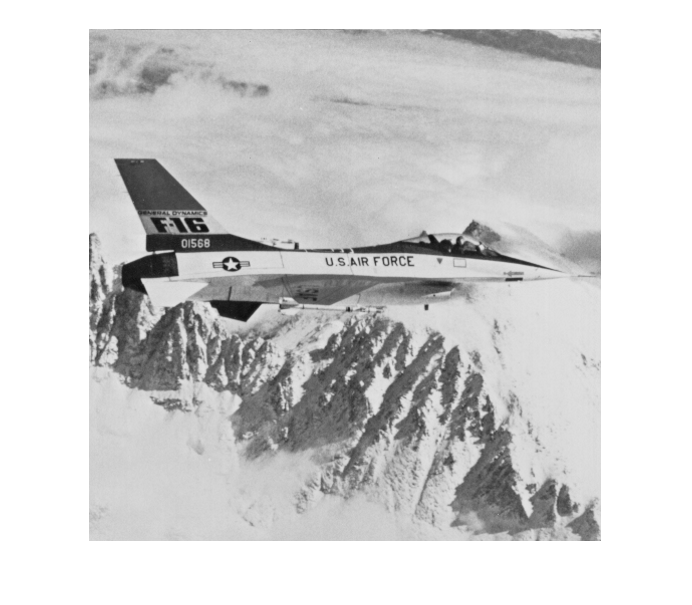

jetplane = jetplane(:,:,1);
imshow(jetplane);

**(1) Scaling and Shearing**

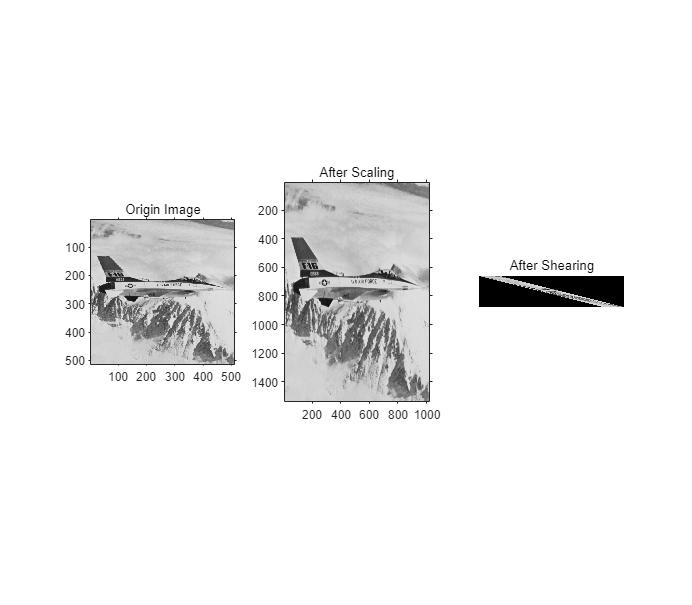

A_scale = [2 0 0;0 3 0;0 0 1];
A_scale = affine2d(A_scale);
O_scale = imwarp(jetplane,A_scale);

%imshow(O_scale);
A_shear = [1 0 0;4 1 0;0 0 1];
A_shear = affine2d(A_shear);
O_shear = imwarp(O_scale,A_shear);

%imshow(O_shear);
subplot(1,3,1);
imshow(jetplane);
title('Origin Image');axis on;
subplot(1,3,2);
imshow(O_scale);
title('After Scaling');axis on;
subplot(1,3,3);
imshow(O_shear);
title('After Shearing');

**(2) Translation and Rotation**

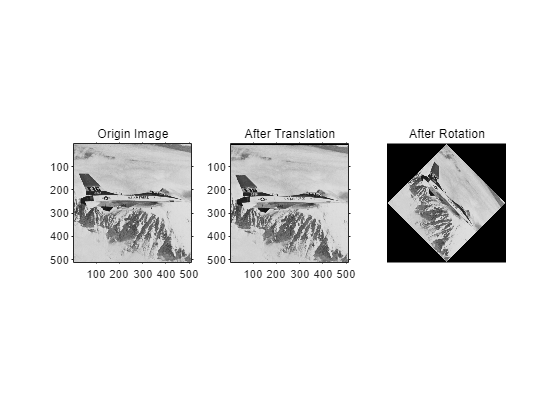

figure;

jet_ref = imref2d(size(jetplane));
A_trans = [1 0 0;0 1 0;-2 5 1];
A_trans = affine2d(A_trans);
[O_trans,jet_ref] = imwarp(jetplane,A_trans,'OutputView',jet_ref);
%O_trans = imtranslate(jetplane,[-2, 5]);

%imshow(O_trans);
A_rot = [sqrt(2)/2 sqrt(2)/2 0;-sqrt(2)/2 sqrt(2)/2 0;0 0 1];
A_rot = affine2d(A_rot);
O_rot = imwarp(jetplane,A_rot);

%imshow(O_rot);
subplot(1,3,1);
imshow(jetplane,jet_ref);
title('Origin Image');axis on;
subplot(1,3,2);
imshow(O_trans,jet_ref);
title('After Translation');axis on;
subplot(1,3,3);
imshow(O_rot);
title('After Rotation');